## ECEN426 Advanced Mechatronic Systems

## Assignment Two - 2021

#### Niels Clayton : 300437590

**1. The supplied robot path begins with six successive steps that are nominally straight forward.**

*a) [5 marks] If there is random disturbance along the robot’s path caused by wheel effects, as characterised by *$\sigma_{\textrm{forward}}$* in the robot’s process noise covariance matrix, then find the expected mean and variance in the robot’s end position at the end of the six steps.*

**Answer.**

Asumming a normal distrobution for the random disturbance, the means will be zero centred (before accounting for steps) and variences will be ${\sigma_{\textrm{forward}} }^2$. 


$$\begin{array}{l}
{\mu_x =60,\;\;\;\;\;\;\;\;\;\;\;\sigma }_x^2 =6\times \sigma_{\textrm{forward}}^2 =6\left(1^2 \right)=6m\\
{\mu_y =0,\;\;\;\;\;\;\;\;\;\;\;\;\;\sigma }_y^2 =6\times \sigma_{\textrm{forward}}^2 =6\left(1^2 \right)=6m\\
{\mu_{\textrm{bearing}} =0,\;\;\;\;\;\sigma }_{\textrm{bearing}}^2 =6\times \sigma_{\textrm{bearing}}^2 =6\left(2^2 \right)={24}^{\circ } 
\end{array}$$


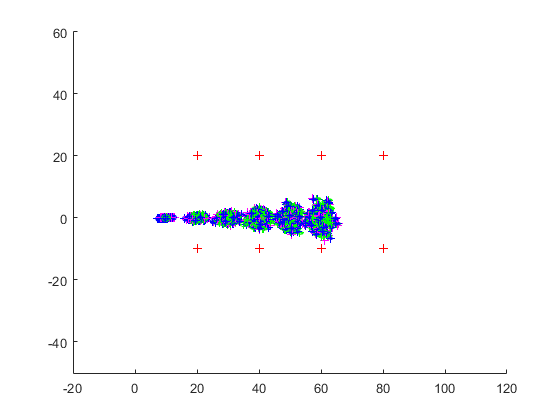

clear; clf; clc;
end_t = 6;
end_pos = [];
for n = 1:100
    run("SLAM.m")
    end_pos = [end_pos; x_robot'];
end

clc;clear;

load("end_pos_100_runs.mat")
sigma_x = var(end_pos(:,1));
mean_x = mean(end_pos(:,1));

sigma_y = var(end_pos(:,2));
mean_y = mean(end_pos(:,2));

sigma_bearing = var(end_pos(:,3));
mean_bearing = mean(end_pos(:,3));

table(mean_x, sigma_x)

ans = 1×2 table
    mean_x    sigma_x
    ______    _______

    59.833    5.7994 


table(mean_y, sigma_y)

ans = 1×2 table
     mean_y     sigma_y
    ________    _______

    -0.14701    6.4548 


table(mean_bearing, sigma_bearing)

ans = 1×2 table
    mean_bearing    sigma_bearing
    ____________    _____________

      -0.40082         25.598    


*b) [5 marks] Consider now the effect of adding the randomness in the robot’s heading as characterised by *$\sigma_{\textrm{bearing}}$*. Again find the covariance of the expected mean and covariance matrix of the robot’s end position after six steps.*

*Hint: You should find an analytical expression for these questions, but can use Matlab (or similar) to do the calculations.*

**2. [10 marks] Using the supplied template code or otherwise, demonstrate empirically whether the end points after six forward steps are spread as predicted according to your calcula- tion. You should do this by finding the end points after at least 100 six step journeys and examining their distribution.**

*Hint: You do not need to do formal statistical distribution comparison for this question (though you could). Just compare the results with your expectation and comment on the results.*

**3. [5 marks] Reduce the system to use only two (or even one) beacon for simplicity. Configure the code for localisation (so the **$P$** matrix for the sensor locations should be set to a small values to indicate that we are very confident about the beacon/landmark locations). Describe qualitatively how the range and heading measurements help constrain the estimate of the robot’s location.**

*Hint: One approach to this problem would be to allow the system to use the measurements to update the estimate only rarely (say every fifth time step) and see how the shape of the posterior estimate differs from that of the prior estimate. You might find it useful to change the noise of the range and heading measurements to see what effect that has on the shape of the posterior distribution.*

**4. [10 marks] As a result of your argument in the previous question, and otherwise, describe how beacons and landmarks should best be spread through an environment. Your discussion should consider the following points.**

- *What would be the minimum number of beacons or landmarks that you think would produce adequate performance? How would they be arranged in a space?*

- *Does the number of landmarks / beacons matter? If so discuss any tradeoffs in the number of landmarks and the performance of the localisation. *

- *As written the code uses sensor noise that is independent of range. However, in practice we often find that the noise in range measurements increases as the range increases. How would this affect your preferred arrangement of landmarks?*

- *Would your answer change if you could use only range measurements, or only heading measurements?*

**5. Consider now the full SLAM problem by setting the initial standard deviation of the landmark positions to 10 m. This indicates that the robot has very littel initial confidence in the landmark locations, but is small enough to avoid any issues with data association.**

*a) [5 marks] Explain how the confidence in the landmark position evolves as a function of time. You should explain qualitatively, but also show representative graphs showing the evolution of the positional certainty. What are the limiting factors in the accuracy with which you can estimate the landmark’s position?*

*Hint: Extracting the diagonal elements of the *$P$ *will give you the variance in the estimates of the positional estimates. For example, *$P_{44}$* will be the variance in the estimate of the x position of the first beacon.*

*b) [5 marks] Imagine that you were given a robot mission that was to perform just mapping. That is, you know perfectly where the robot is at all times (using GPS or similar) and your task is to determine the location of a set of landmarks as quickly as possible. Describe qualitatively the path that you would program the robot to take. Start your description with the case of a single landmark, and then generalise your argument to the case of an arbitrary number of landmarks.*

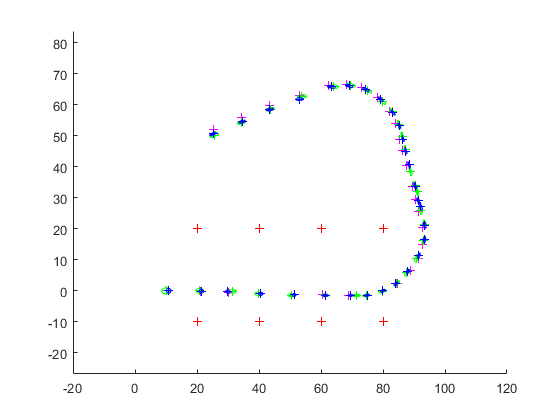

clc; clear; clf;
end_t = 30;
run("SLAM.m")